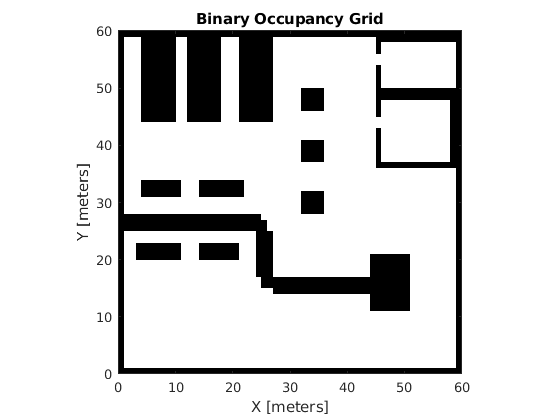

load warehouseMaps.mat logicalMap
map = binaryOccupancyMap(logicalMap);
show(map)


% initialize global node
rosinit("http://localhost:11311")

Initializing global node /matlab_global_node_29835 with NodeURI http://sskulka-Legion-5-15ACH6:36411/



% subscribe to odometry data
odom = rossubscriber('/odom');  
odomdata = receive(odom,3);

% publish velocity
velPub = ros.Publisher([], '/cmd_vel', 'geometry_msgs/Twist');

pose = odomdata.Pose.Pose;

speed = rosmessage(velPub);

% set goal point
goal = pose.Position;
goal.X = 0.0;
goal.Y = 5.0;

%frequency of the loop (rate of execution)
r = rateControl(6);

tic;
while toc<1000
    
    odomdata = receive(odom,3);
    pose = odomdata.Pose.Pose;
    
    % get current position of the robot
    x = pose.Position.X;
    y = pose.Position.Y;
    
    % get current orientation (yaw) of the robot
    quat = pose.Orientation;
    angles = quat2eul([quat.W quat.X quat.Y quat.Z]);
    theta = angles(1);
    
    % difffernce between the present position and goal position
    dist_x = goal.X - x;
    dist_y = goal.Y - y;
    
    % angle between the current orientation of the robot (about z-axis) and
    % the goal position from the present position
    angle_to_goal = atan2(dist_y, dist_x);
    
    
    % the robot will initially estimate the angle and turn towards it at a
    % given angular velocity and then starts moving towards it at a given   
    % linear velocity until it reaches the end position
    if (abs(angle_to_goal - theta) < 0.1)
        speed.Linear.X = 0.6;
        speed.Angular.Z = 0.0;
    elseif (abs(x-goal.X)<0.1 && abs(y-goal.Y)<0.1)
        speed.Linear.X = 0.0;
        speed.Angular.Z = 0.0;
    else
        speed.Linear.X = 0.0;
        speed.Angular.Z = 0.25;
    end
    
    % send daata to the robot in Gazebo
    send(velPub,speed);
    
    waitfor(r);
    
end

% shutdown MATLAB rosnode
rosshutdown